# **sBAXTER**

# PLANEACIÓN DE TRAYECTORIAS

## **CINÉMATICA DIRECTA**

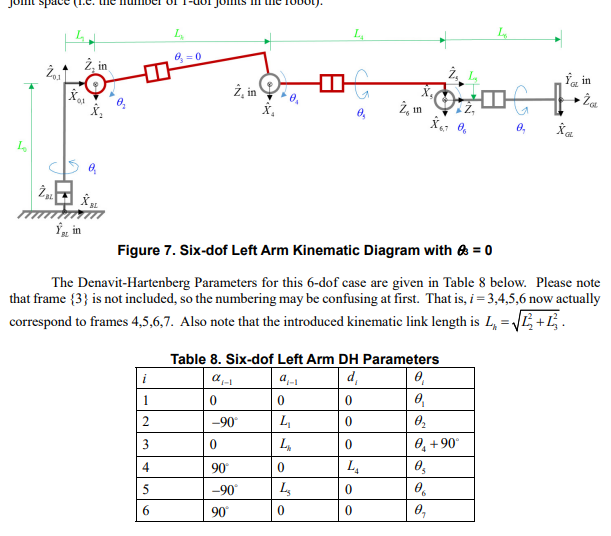

Ejemplo de la matriz de posicion en la cual los valores de X,Y ,Z ya son declarados por lo cual

se puede despejar los valores de th2 y th4

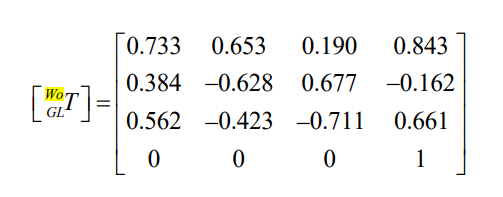

clc
clear all
sympref('FloatingPointOutput',true)

ans = logical
   1


syms th1 th2 th3 th4 th5 th6 th7 L1 L4 L5 LH

%%%en m
l0=270.35/1000

l0 = 0.2704

l1=69/1000;
l2=364.35/1000;
l3=69/1000;
l4=374.29/1000;
l5=10/1000;
l6=368.30/1000;
h=278/1000;
H=64/1000;
L=1104/1000;
%%"en cinematica directa" primero se proporciona una matriz de
%%transfomracion desde wo(centro) hasta G(manipulador) la cual se debe
%%transformar a una matriz de transformacion de los grados de libertad

TwoGL=[0.733 0.653 0.190 0.843;
       0.384 -0.628 0.677 -0.162;
       0.562 -0.423 -0.711 0.661;
       0       0      0      1]

TwoGL =     0.7330    0.6530    0.1900    0.8430
    0.3840   -0.6280    0.6770   -0.1620
    0.5620   -0.4230   -0.7110    0.6610
         0         0         0    1.0000


%%TwoGL=[0.566 0.674 0.475 1.026;-0.021 -0.564 0.825 0.039;0.824 -0.477 -0.306 0.788;0 0 0 1]
TwoBL=[sqrt(2)/2 sqrt(2)/2 0 h; -sqrt(2)/2 sqrt(2)/2 0 -H; 0 0 1 L; 0 0 0 1];
%TwoBR=[-sin(45) cos(45) 0 -h;-sin(45) -sin(45) 0 -H;0 0 1 L;0 0 0 1];
%para el otro brazo
T6Gl=[1 0 0 0; 0 1 0 0; 0 0 1 l6; 0 0 0 1];
TBlO=[1 0 0 0; 0 1 0 0; 0 0 1 l0; 0 0 0 1];
TWoO=TwoBL*TBlO;
T0t6=inv(TWoO)*TwoGL*inv(T6Gl)

T0t6 =     0.2468    0.9058   -0.3444    0.5956
    0.7898    0.0177    0.6131    0.1044
    0.5620   -0.4230   -0.7110   -0.4515
         0         0         0    1.0000



%%%%%%%%%%%%%%%%tomando los valores de ejemplo de la matriz
x=T0t6(1,4)

x = 0.5956

y=T0t6(2,4)

y = 0.1044

z=T0t6(3,4)

z = -0.4515

Th1= atan2((y),(x)) %%% ya que tecnicamente seria atan2(Sin(th1),cos(th1)) segun el despeje, sin embargo

Th1 = 0.1736

                  %%% solo nos estarian dando el valor de th1 sino solo los
                  %%% resutaldos de sin y cos o usando los valores de x y y
                  %%% que contienen th1%%%%%%%%%%%el resultado es en
                  %%% radianes
tt1=rad2deg(Th1)                  

tt1 = 9.9441

                  
lh=sqrt(l2^2+l3^2);
E=2*lh*(l1-(x/cos(Th1)));%% ni idea de que hago con x con esta variable
F=2*lh*z;
G=((x^2)/(cos(Th1)^2))+(l1^2)+(lh^2)-(l4^2)+(z^2)-2*(l1*x/cos(Th1));
%%%%%%%%%%%%del libro
Th2_2=2*atan((-F+sqrt(E^2+F^2-G^2))/(G-E))

Th2_2 = 1.0494

Th2_1=2*atan((-F-sqrt(E^2+F^2-G^2))/(G-E))%%%codo arriba

Th2_1 = 0.3512


tt2=rad2deg(Th2_1)

tt2 = 20.1214

tt2b=rad2deg(Th2_2)

tt2b = 60.1245

Th3=0;

Th4_1=atan2((-z-lh*sin(Th2_1)),((x/cos(Th1))-l1-lh*cos(Th2_1)))-Th2_1;
Th4_2=atan2((-z-lh*sin(Th2_2)),((x/cos(Th1))-l1-lh*cos(Th2_2)))-Th2_2;%%%codo abajo
tt4=rad2deg(Th4_1)

tt4 = 39.8102

tt4b=rad2deg(Th4_2)

tt4b = -39.8102

%%%%%%%%%%%%%%%%%%obtener R3to6
for i=1:3
    for j=1:3
    Ro06(i,j)=T0t6(i,j);
    end
end
R03CA=[-cos(Th1)*sin(Th2_1+Th4_1) -cos(Th1)*cos(Th2_1+Th4_1) -sin(Th1) ;
       -sin(Th1)*sin(Th2_1+Th4_1) -sin(Th1)*cos(Th2_1+Th4_1)  cos(Th1);
       -cos(Th2_1+Th4_1)           sin(Th2_1+Th4_1)      0     ];

R03CB=[-cos(Th1)*sin(Th2_2+Th4_2) -cos(Th1)*cos(Th2_2+Th4_2) -sin(Th1);
       -sin(Th1)*sin(Th2_2+Th4_2) -sin(Th1)*cos(Th2_2+Th4_2)  cos(Th1) ;
       -cos(Th2_2+Th4_2)           sin(Th2_2+Th4_2)     0      ];

R3t06CA=transpose(R03CA)*Ro06;
R3t06CB=transpose(R03CB)*Ro06;

%%%%%%%%%%%%%%%%%%
Th5_1=atan2(R3t06CA(3,3),R3t06CA(1,3));
tt5=rad2deg(Th5_1)

tt5 = 49.9207

Th7_1=atan2(-R3t06CA(2,2),R3t06CA(2,1)) ;
Th6_1=atan2(R3t06CA(2,1)/cos(Th7_1),-R3t06CA(2,3));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Th5_2=atan2(R3t06CB(3,3),R3t06CB(1,3));
tt5b=rad2deg(Th5_1)

tt5b = 49.9207

Th7_2=atan2(-R3t06CB(2,2),R3t06CB(2,1)) ;
Th6_2=atan2(R3t06CB(2,1)/cos(Th7_2),-R3t06CB(2,3));
disp('Angulos con el codo arriba requeridos')

Angulos con el codo arriba requeridos


ThangBRA=([th1 th2 th3 th4 th5 th6 th7;rad2deg(Th1) rad2deg(Th2_1) 0 rad2deg(Th4_1) rad2deg(Th5_1) rad2deg(Th6_1) rad2deg(Th7_1)])

$$ThangBRA = \left(\begin{array}{ccccccc} {\mathrm{th}}_{1} & {\mathrm{th}}_{2} & {\mathrm{th}}_{3} & {\mathrm{th}}_{4} & {\mathrm{th}}_{5} & {\mathrm{th}}_{6} & {\mathrm{th}}_{7}\\ 9.9441 & 20.1214 & 0 & 39.8102 & 49.9207 & 60.1012 & 70.0158 \end{array}\right)$$


disp('Angulos con el codo abajo requeridos')

Angulos con el codo abajo requeridos


ThangBAB=([th1 th2 th3 th4 th5 th6 th7;rad2deg(Th1) rad2deg(Th2_2) 0 rad2deg(Th4_2) rad2deg(Th5_2) rad2deg(Th6_2) rad2deg(Th7_2)])

$$ThangBAB = \left(\begin{array}{ccccccc} {\mathrm{th}}_{1} & {\mathrm{th}}_{2} & {\mathrm{th}}_{3} & {\mathrm{th}}_{4} & {\mathrm{th}}_{5} & {\mathrm{th}}_{6} & {\mathrm{th}}_{7}\\ 9.9441 & 60.1245 & 0 & -39.8102 & 41.5747 & 88.3935 & 99.2561 \end{array}\right)$$

%%Tenemos que usar entonces cinematica directa para mover el robot
%%%aun tomado el baxter como un brazo humano tenemos que del DH
%%% tomamos la tabla del documento guia las transformadas son


%%%%%%%%%%%%%%%%%%%5no se porque no esta dando igual a la del
%%%%%%%%%%%%%%%%%%%doc%%%%%%%%%%%%%%%%%%%%
nullp=[0;0;0];
nullrot=[1 0 0; 0 1 0; 0 0 1];%%% aux para los desplazamientos
DHbx=[0     0   0  th1;
     -pi/2  L1  0  th2;
      0     LH  0  th4+pi/2;
      pi    0   L4 th5;
     -pi/2  L5  0  th6;
      pi    0   0  th7]

$$DHbx = \left(\begin{array}{cccc} 0 & 0 & 0 & {\mathrm{th}}_{1}\\ -1.5708 & L_{1} & 0 & {\mathrm{th}}_{2}\\ 0 & \mathrm{LH} & 0 & {\mathrm{th}}_{4}+1.5708\\ 3.1416 & 0 & L_{4} & {\mathrm{th}}_{5}\\ -1.5708 & L_{5} & 0 & {\mathrm{th}}_{6}\\ 3.1416 & 0 & 0 & {\mathrm{th}}_{7} \end{array}\right)$$

for i=1:6
        alpha=DHbx(i,1);
        a=DHbx(i,2);
        d=DHbx(i,3);
        theta=DHbx(i,4);
        fname=['T',num2str(i)];
        C=[cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);
            sin(theta) cos(theta)*cos(alpha)  -cos(theta)*sin(alpha) a*sin(theta);
            0,sin(alpha),cos(alpha),d;
            0,0,0,1];
        B.(fname)=C;%%ayuda haciendo una estructura de datos para almacenar variables cambiantes
        
end
T01=B.T1

$$T01 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\right) & -\sin\left({\mathrm{th}}_{1}\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{1}\right) & \cos\left({\mathrm{th}}_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12=B.T2

$$T12 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\right) & 0 & -\sin\left({\mathrm{th}}_{2}\right) & L_{1}\,\cos\left({\mathrm{th}}_{2}\right)\\ \sin\left({\mathrm{th}}_{2}\right) & 0 & \cos\left({\mathrm{th}}_{2}\right) & L_{1}\,\sin\left({\mathrm{th}}_{2}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23=B.T3

$$T23 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{4}+1.5708\right) & -\sin\left({\mathrm{th}}_{4}+1.5708\right) & 0 & \mathrm{LH}\,\cos\left({\mathrm{th}}_{4}+1.5708\right)\\ \sin\left({\mathrm{th}}_{4}+1.5708\right) & \cos\left({\mathrm{th}}_{4}+1.5708\right) & 0 & \mathrm{LH}\,\sin\left({\mathrm{th}}_{4}+1.5708\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34=B.T4

$$T34 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{5}\right) & \sin\left({\mathrm{th}}_{5}\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{5}\right) & -\cos\left({\mathrm{th}}_{5}\right) & 0 & 0\\ 0 & 0 & -1 & L_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T45=B.T5

$$T45 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{6}\right) & 0 & -\sin\left({\mathrm{th}}_{6}\right) & L_{5}\,\cos\left({\mathrm{th}}_{6}\right)\\ \sin\left({\mathrm{th}}_{6}\right) & 0 & \cos\left({\mathrm{th}}_{6}\right) & L_{5}\,\sin\left({\mathrm{th}}_{6}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T56=B.T6

$$T56 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{7}\right) & \sin\left({\mathrm{th}}_{7}\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{7}\right) & -\cos\left({\mathrm{th}}_{7}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T03=T01*T12*T23;
T36=T34*T45*T56;
T06=T03*T36